# State Space Models

We begin by writing the state space model for a an *individual (Ai)* axis

syms I I_dot theta_ddot_g V_s R_m L_m V_emf theta_dot_m tau_m G theta_dot_g b J K_e K_i

u_i = V_s

$$u\_i = V_{s}$$


x_i = [
    I
    theta_dot_g
]

$$x\_i = \left(\begin{array}{c} \text{I}\\ {\dot{\theta }}_{g} \end{array}\right)$$


x_dot_i = [
    I_dot
    theta_ddot_g
]

$$x\_dot\_i = \left(\begin{array}{c} \dot{I}\\ {\ddot{\theta }}_{g} \end{array}\right)$$


A_i = [
    -R_m/L_m    -K_e/(L_m*G);
    K_i/(J*G)  -b/J
]

$$A\_i = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G\,L_{m}}\\ \frac{K_{i}}{G\,J} & -\frac{b}{J} \end{array}\right)$$

B_i = [
    1/L_m;
    0
]

$$B\_i = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

## State Space Models for Individual Axis

syms I_pan  I_dot_pan  theta_ddot_g_pan  V_s_pan R_m_pan L_m_pan V_emf_pan theta_dot_m_pan tau_m_pan G_pan theta_dot_g_pan b_pan J_pan K_e_pan K_i_pan
syms I_tilt I_dot_tilt theta_ddot_g_tilt V_s_tilt R_m_tilt L_m_tilt V_emf_tilt theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e_tilt K_i_tilt

s      = [ I      I_dot      theta_ddot_g      V_s      R_m L_m V_emf theta_dot_m      tau_m      G      theta_dot_g      b      J      K_e K_i ];
s_pan  = [ I_pan  I_dot_pan  theta_ddot_g_pan  V_s_pan  R_m L_m V_emf theta_dot_m_pan  tau_m_pan  G_pan  theta_dot_g_pan  b_pan  J_pan  K_e K_i ];
s_tilt = [ I_tilt I_dot_tilt theta_ddot_g_tilt V_s_tilt R_m L_m V_emf theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e K_i ];

x_pan  = subs(x_i, s, s_pan)

$$x\_pan = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{pan}} \end{array}\right)$$

x_tilt = subs(x_i, s, s_tilt)

$$x\_tilt = \left(\begin{array}{c} I_{\mathrm{tilt}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$


x_dot_pan  = subs(x_dot_i, s, s_pan);
x_dot_tilt = subs(x_dot_i, s, s_tilt);

u_pan  = subs(u_i, s, s_pan);
u_tilt = subs(u_i, s, s_tilt);

A_pan  = subs(A_i, s, s_pan)

$$A\_pan = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{pan}}\,L_{m}}\\ \frac{K_{i}}{G_{\mathrm{pan}}\,J_{\mathrm{pan}}} & -\frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} \end{array}\right)$$

A_tilt  = subs(A_i, s, s_tilt)

$$A\_tilt = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{tilt}}\,L_{m}}\\ \frac{K_{i}}{G_{\mathrm{tilt}}\,J_{\mathrm{tilt}}} & -\frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B_pan  = subs(B_i, s, s_pan)

$$B\_pan = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

B_tilt  = subs(B_i, s, s_tilt)

$$B\_tilt = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

We can now combine these into one large model

x = [ x_pan; x_tilt ]

$$x = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{pan}}\\ I_{\mathrm{tilt}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$

x_dot = [ x_dot_pan; x_dot_tilt ]

$$x\_dot = \left(\begin{array}{c} {\dot{I}}_{\mathrm{pan}}\\ {\ddot{\theta }}_{g,\mathrm{pan}}\\ {\dot{I}}_{\mathrm{tilt}}\\ {\ddot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$


A_sym = [
    A_pan    zeros(2);
    zeros(2) A_tilt
]

$$A\_sym = \left(\begin{array}{cccc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{pan}}\,L_{m}} & 0 & 0\\ \frac{K_{i}}{G_{\mathrm{pan}}\,J_{\mathrm{pan}}} & -\frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} & 0 & 0\\ 0 & 0 & -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{tilt}}\,L_{m}}\\ 0 & 0 & \frac{K_{i}}{G_{\mathrm{tilt}}\,J_{\mathrm{tilt}}} & -\frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B_sym = [
    B_pan              zeros(size(B_pan));
    zeros(size(B_pan)) B_tilt
]

$$B\_sym = \left(\begin{array}{cc} \frac{1}{L_{m}} & 0\\ 0 & 0\\ 0 & \frac{1}{L_{m}}\\ 0 & 0 \end{array}\right)$$

% Defining outputs to be the velocities
C = [
    0 1 0 0;
    0 0 0 1
];
D = 0;


u = [ u_pan; u_tilt ]

$$u = \left(\begin{array}{c} V_{s,\mathrm{pan}}\\ V_{s,\mathrm{tilt}} \end{array}\right)$$

## Adding Real Parameters

G_tilt_real = 15/48; % measured by counting gear teeth on the system
G_pan_real = G_tilt_real;

% Use moment of inertia calculated in 'inertia.mlx'
J_tilt_real = double(J_tilt_out)

J_tilt_real = 0.0213

J_pan_real = vpa(J_pan_out)

$$J\_pan\_real = 0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512932$$

% Sines are hard to work with in state space models, we therefore simply
% take the largest value of the moment of inertia.
J_pan_real = double(subs(J_pan_real, theta_tilt, pi/2))

J_pan_real = 0.1031


% Motor constants (K_e = K_i in SI units)
K_i_real = 0.509;
K_e_real = K_i_real;
R_m_real = 7.101;
L_m_real = 3.4E-3;

% Friction coefficients
b_pan_real  = 0 % TODO: system identification

b_pan_real = 0

b_tilt_real = 0 % TODO: system identification

b_tilt_real = 0



% substitute into the model
s      = [ b_pan      b_tilt      L_m      G_pan      b_pan J_pan      K_e_pan  R_m      L_m_tilt G_tilt      b_tilt J_tilt      K_e      K_i      ];
s_real = [ b_pan_real b_tilt_real L_m_real G_pan_real b_pan J_pan_real K_e_real R_m_real L_m_real G_tilt_real b_tilt J_tilt_real K_e_real K_i_real ];

A = double(subs(A_sym, s, s_real))

A = 1.0e+03 *

   -2.0885   -0.4791         0         0
    0.0158         0         0         0
         0         0   -2.0885   -0.4791
         0         0    0.0766         0



eig(A)

ans = 1.0e+03 *

   -2.0849
   -0.0036
   -2.0708
   -0.0177



B = double(subs(B_sym, s, s_real))

B =   294.1176         0
         0         0
         0  294.1176
         0         0


C

C =      0     1     0     0
     0     0     0     1


D

D = 0

y = C*x + D*u

$$y = \left(\begin{array}{c} {\dot{\theta }}_{g,\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$

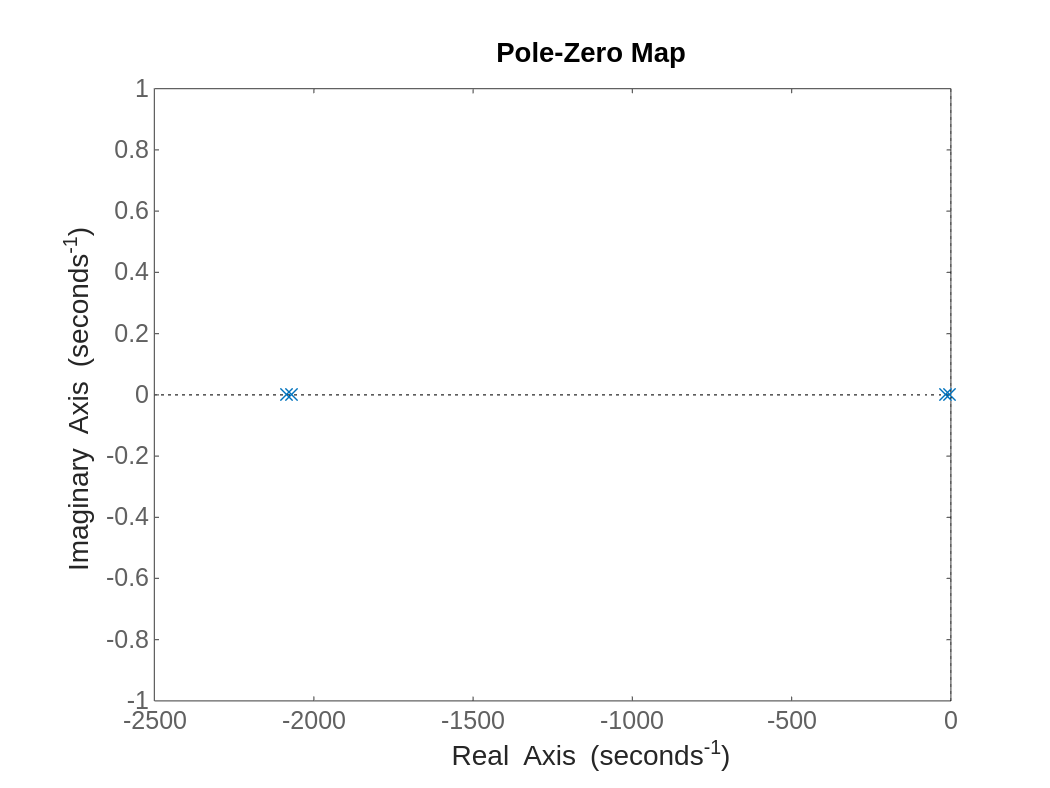



sys = ss(A, -B, C, D);
pzmap(sys)

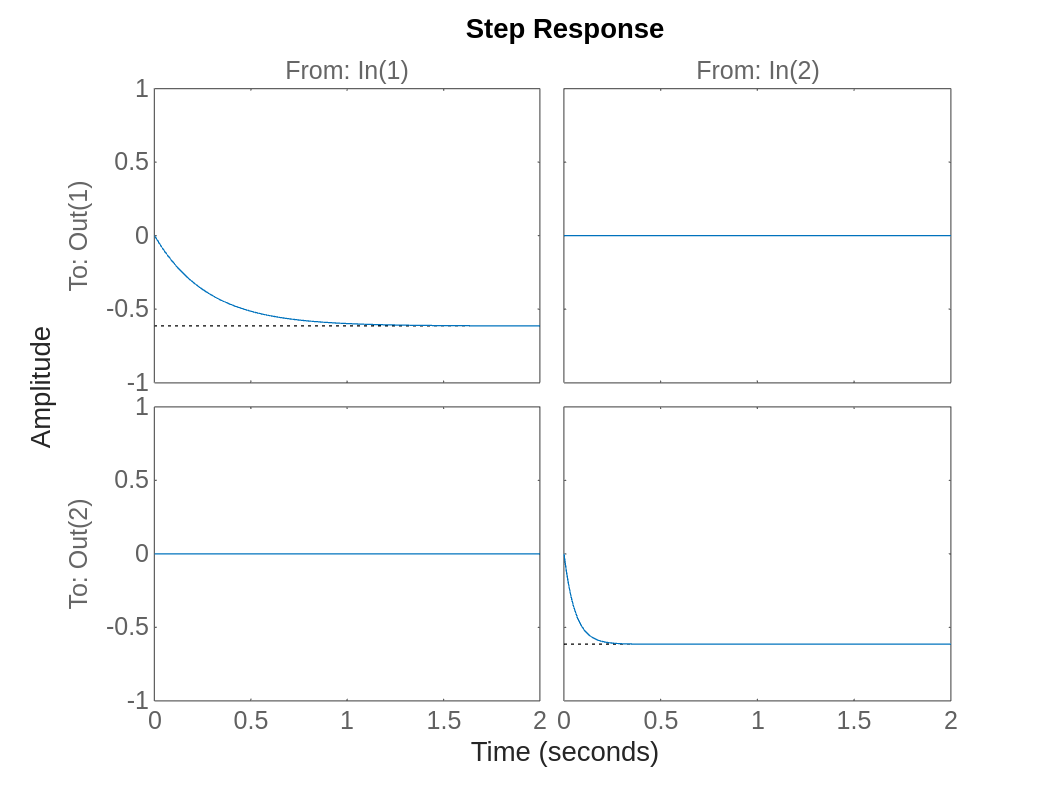

step(sys)

# Controlability

Con = [B A*B];
rank(Con)

ans = 4

The system is controlable as the controlability has rank equal to the number of system state variables

# Regulator - State Feedback

t_s = 1;
alpha = 5;
sigma = -log(alpha/100)/t_s

sigma = 2.9957

A_e = [
        A zeros(4,2);
        C zeros(2,2);
   ]

A_e = 1.0e+03 *

   -2.0885   -0.4791         0         0         0         0
    0.0158         0         0         0         0         0
         0         0   -2.0885   -0.4791         0         0
         0         0    0.0766         0         0         0
         0    0.0010         0         0         0         0
         0         0         0    0.0010         0         0


B_e = [
        B;
        zeros(2,2);
]

B_e =   294.1176         0
         0         0
         0  294.1176
         0         0
         0         0
         0         0


C_e = [
        C zeros(2,2);
]

C_e =      0     1     0     0     0     0
     0     0     0     1     0     0


## Place Poles

poles = [-5 -5 -6 -6 -7 -7];


F_e = place(A_e, -B_e, poles)

F_e =     7.0398    1.6058   -0.0000   -0.0000   -0.0452   -0.0000
    0.0000    0.0000    7.0398    1.6241   -0.0000   -0.0093


eig(A_e + B_e * F_e)

ans =   -7.0000 + 0.0000i
  -7.0000 - 0.0000i
  -5.0000 + 0.0000i
  -5.0000 + 0.0000i
  -6.0000 + 0.0000i
  -6.0000 + 0.0000i



latex(vpa(F_e, 3))

ans = '\left(\begin{array}{cccccc} 7.04 & 1.61 & -5.39e-16 & -8.08e-17 & -0.0452 & -2.29e-16\\ 7.24e-17 & 1.81e-17 & 7.04 & 1.62 & -3.85e-17 & -0.00932 \end{array}\right)'

## Split into F and FI

F = F_e(:, 1:4)

F =     7.0398    1.6058   -0.0000   -0.0000
    0.0000    0.0000    7.0398    1.6241


FI = F_e(:, 5:6)

FI =    -0.0452   -0.0000
   -0.0000   -0.0093


eig(A + B*F)

ans =   -9.0000 + 5.0990i
  -9.0000 - 5.0990i
  -9.0000 + 5.0990i
  -9.0000 - 5.0990i


# Observer

Observer matrix

O = [C; C*A; C*A^2; C*A^3];
rank(O)

ans = 4

The system poles where placed at

poles

poles =     -5    -5    -6    -6    -7    -7


The oberver poles must be at around seven times more to the left

c = 7;
observer_poles = poles(:, 3:6)*c

observer_poles =    -42   -42   -49   -49



L = place(A', -C', observer_poles)'

L = 1.0e+05 *

   -2.6365   -0.0000
    0.0200    0.0000
    0.0000   -0.5399
   -0.0000    0.0200


eig(A + L*C)

ans =   -42.0000
  -42.0000
  -49.0000
  -49.0000


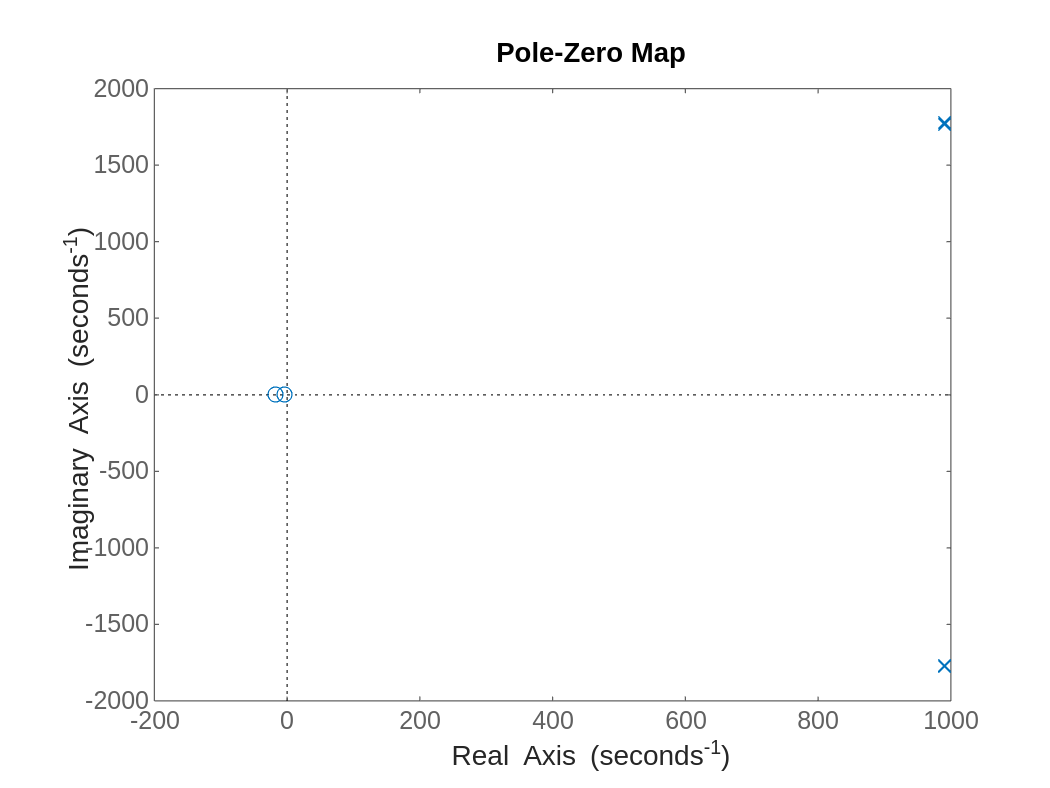


observer = ss(A+B*F+L*C, -L, F, zeros(2));

pzmap(observer)